[audio, fs] = audioread('long_tailed_tit.flac');

sound(audio, fs);

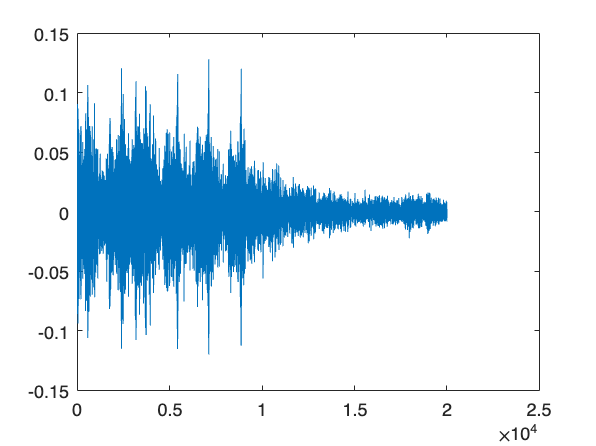

% extend for multiple syllables
x = audio(2e4:4e4);
plot(x);

sound(x,fs);

% try up to 20khz
gammaFiltBank = gammatoneFilterBank(NumFilters=64,SampleRate=fs);
audioOut = gammaFiltBank(x);

cochlea1 = log10(cochleagram(audioOut, fs*0.020, fs*0.010));
cochlea2 = log10(cochleagram(audioOut, fs*0.200, fs*0.010));
cochlea3 = avg_window(cochlea1, 11);
cochlea4 = avg_window(cochlea1, 23);
all_cochleas = [cochlea1; cochlea2; cochlea3; cochlea4];

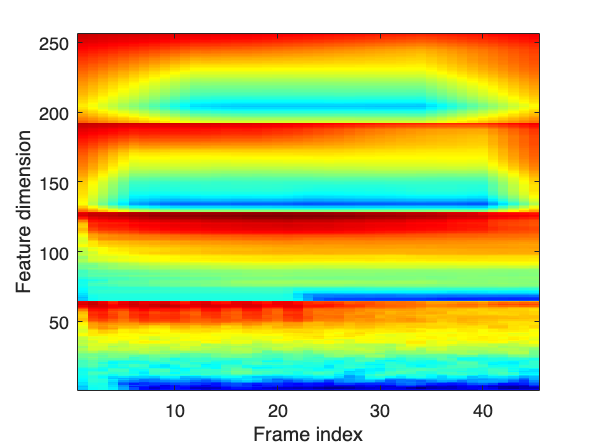

imagesc(all_cochleas);
colormap jet;
ylabel('Feature dimension');
xlabel('Frame index');
set(gca,'YDir','normal');

function avg = avg_window(data, span)

kernel = ones(span) / span^2;

avg = conv2(data, kernel, 'same');

end

function out = cochleagram(in, winLength, winShift)

[sigLength, numChan] = size(in);

M = floor(sigLength/winShift);
increment = winLength / winShift;

out = zeros(numChan, M);

for m = 1:M
    for i = 1:numChan
        if m < increment
            out(i,m) = in(1:m*winShift,i)'*in(1:m*winShift,i);
        else
            startpoint = floor((m-increment)*winShift);
            to = floor(startpoint+winLength);
            out(i,m) = in(startpoint+1:to,i)'*in(startpoint+1:to,i);
        end
    end
end

end